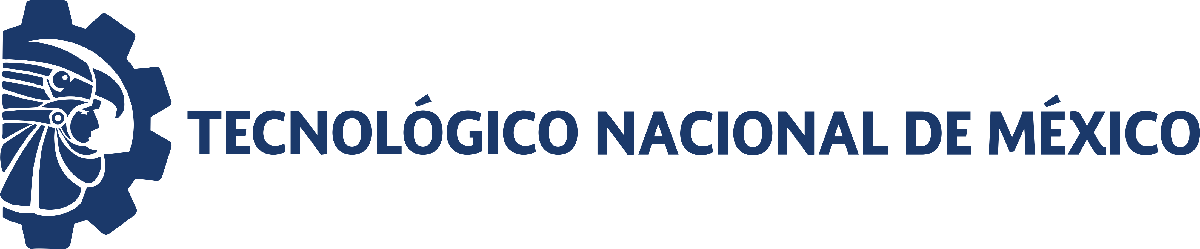                                 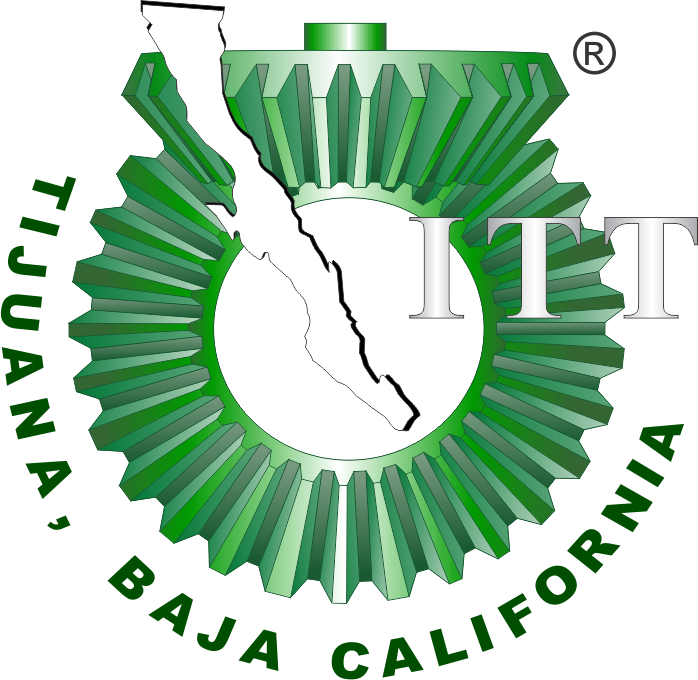

# Práctica Dos: Modelado y control del sistema cardiovascular mediante el modelo Windkessel

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

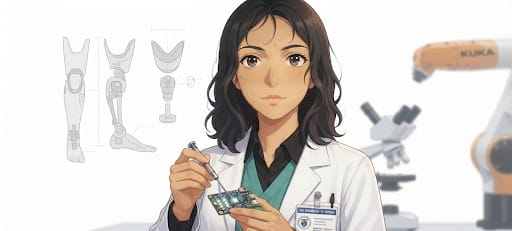

Nombre del alumno: Reyes Zamudio Mariant

Número de control: 23212228

Correo institucional: l23212228**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema')
parameters.StopTime = '15';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x=sim('sistema',parameters);
t_data = (0:0.1:15)';
t=(0:0.001:15)';
Pa=interp1(t_data, x.Pa, t, 'previous');
writematrix(Pa,'signal.xlsx');


## Respuesta Normotenso

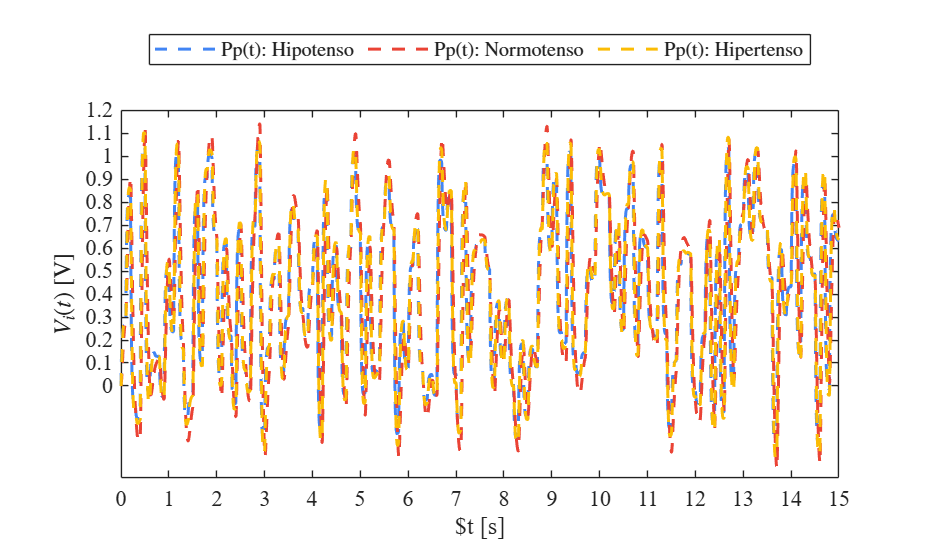

x = sim('sistema',parameters);
plotsignals(x.t,x.PpN,x.PpL,x.PpH,x.PIDL,x.PIDH,"Normotenso")

## Respuesta Hipotenso

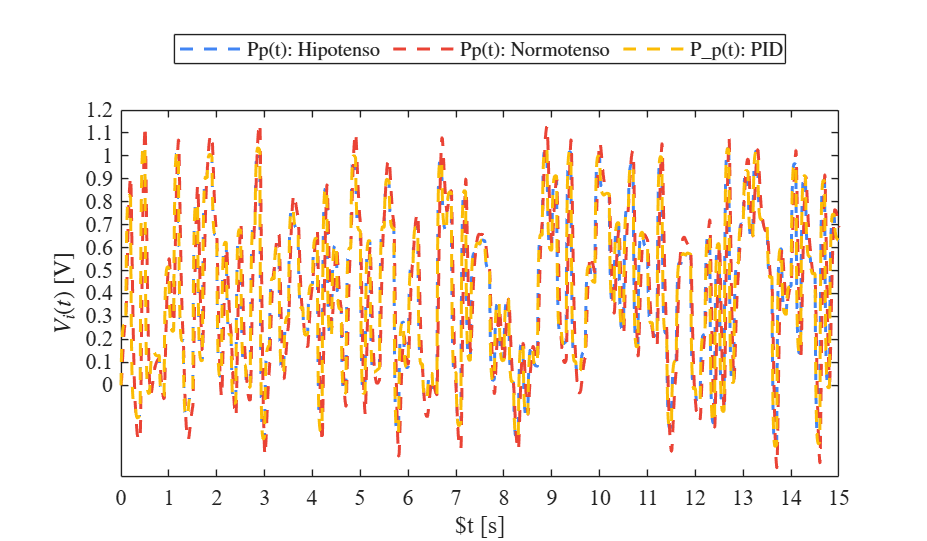

x1 = sim('sistema',parameters);
plotsignals(x1.t,x1.PpN,x1.PpL,x1.PpH,x1.PIDL,x1.PIDH,"Hipotenso")

## Respuesta Hipertenso

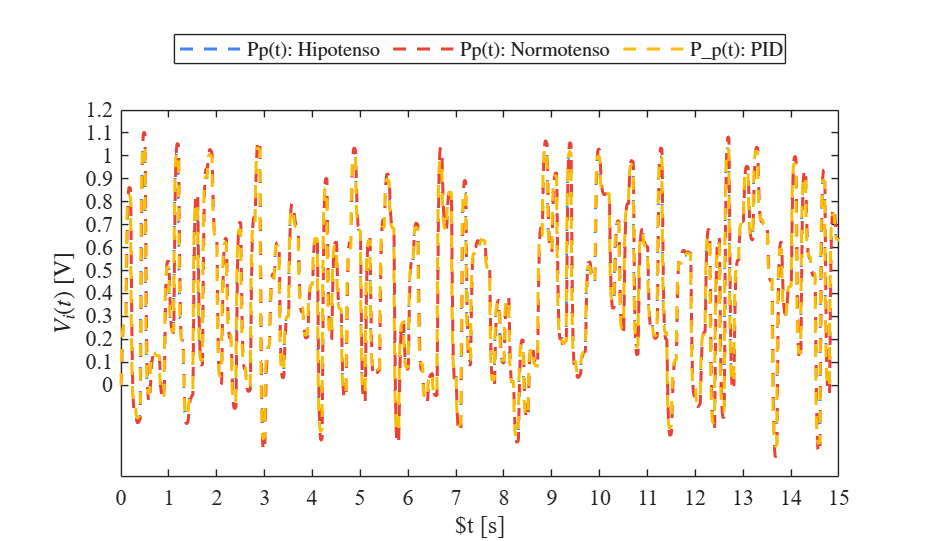

x2 = sim('sistema',parameters);
plotsignals(x2.t,x2.PpN,x2.PpL,x2.PpH,x2.PIDL,x2.PIDH,"Hipertenso")

## **Función: Respuestas de la simulación**

function plotsignals(t,PpN,PpL,PpH,PIDL,PIDH,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position', [0.5,0.5,12,7])
    set(gca, 'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [66, 133, 244]/255;  
    clr2 = [234, 67, 53]/255;   
    clr3 = [251, 188, 5]/255;   
    order = [clr1; clr2; clr3]; colororder(order)


    xlabel('$t [s]','Interpreter','latex')
    ylabel('$V_i(t)$ [V]', 'Interpreter','latex')

    xlim([0 15]); xticks(0:1:15)
    ylim([-0.4 1.2]); yticks(0:0.1:1.2)

    if signal == "Normotenso"

        plot(t,PpN,'--',t,PpL,'--',t,PpH,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
            1:1e3:length(t));
        L = legend('Pp(t): Hipotenso','Pp(t): Normotenso','Pp(t): Hipertenso');
        set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
          
    elseif signal == "Hipotenso"
        plot(t,PpN,'--',t,PpL,'--',t,PIDL,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
            1:1e3:length(t));
        L = legend('Pp(t): Hipotenso','Pp(t): Normotenso','P_p(t): PID');
        set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
       


    elseif signal == "Hipertenso"
        plot(t,PpN,'--',t,PpH,'--',t,PIDH,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
            1:1e3:length(t));
        L = legend('Pp(t): Hipotenso','Pp(t): Normotenso','P_p(t): PID');
        set(L,'interpreter','latex','location','northoutside','orientation','horizontal')

    end
   saveas(gcf, char(signal + "_matlab.pdf"))

end